clc, clear, close all
addpath([cd,'\Cars'])
addpath([cd,'\Tracks'])

## Environment Properties

World.p = 1.225; % kg/m3
World.grip_scale = 1; 

## Load Track

Track = load("formula_south.mat");
Track.RWP = 1./Track.KWP;
if Track.start_from_zero
    Track.RWP(1) = 0.01;
end
Track.RWP(~isfinite(Track.RWP)) = 10000;

## Load Cars

Paddock(1).car = Car4W("car_01_stock.json",...
                       "power_01_wr450.json",...
                       World);
Paddock(2).car = Car4W("car_06_no-aero-new-tire.json",...
                       "power_01_wr450.json",...
                       World);
% Paddock(3).car = Car4W("car_03_low-aero.json",...
%                        "power_01_wr450.json",...
%                        World);
% Paddock(4).car = Car4W("car_01_stock.json",...
%                        "power_01e_emrax.json",...
%                        World);

## Use Walking Algorithm on Each Car

for i = 1:length(Paddock)
    disp("Calculating apexes for Car "+i+" ...")
    Log(i).VWP = cornVel(Paddock(i).car,Track.SWP,Track.RWP);
    
    disp("Walking points for Car "+i+" ...")
    [Log(i).MVWP,Log(i).GX,Log(i).GY] = walk(Paddock(i).car,Track.SWP,Log(i).VWP,Track.RWP);
    
    Paddock(i).laptime = lapTime(Track.SWP,Log(i).MVWP);
    Paddock(i).MVWP = Log.MVWP;
    fprintf("Car "+i+" completed track in %3.3f seconds.\n",Paddock(i).laptime);
    fprintf("\n\n");
end

Calculating apexes for Car 1 ...


Walking points for Car 1 ...


100/138


Car 1 completed track in 29.591 seconds.


Calculating apexes for Car 2 ...


Walking points for Car 2 ...


100/138


Car 2 completed track in 30.649 seconds.


## Plot Results

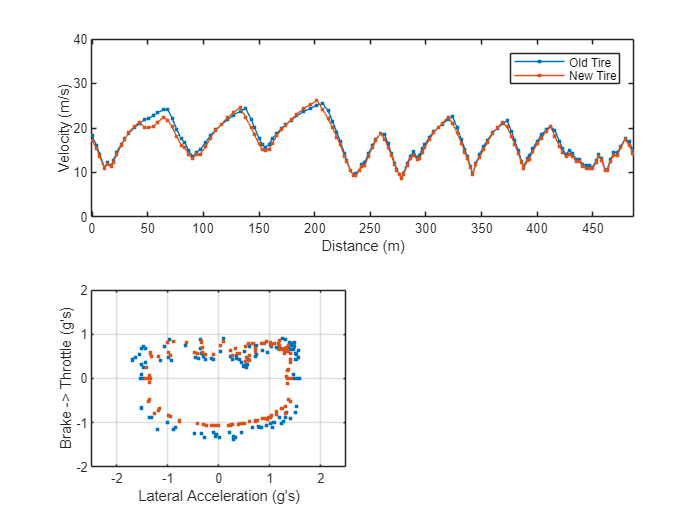

% figure("Visible","on","Units","normalized","Position",[0.10,0.05,0.80,0.80])
tiledlayout(2,4);
nexttile([1,4]);
legend('Location','northwest');
for i = 1:length(Paddock)
    plot(Track.SWP,Log(i).MVWP,'.-','DisplayName',"Car "+i);
    hold on;
end
xlim([-1,Track.SWP(end)+1])
ylim([0,40])
xlabel("Distance (m)")
ylabel("Velocity (m/s)")
legend("Old Tire","New Tire")

nexttile([1,2]);
legend('Location','northwest');
for i = 1:length(Paddock)
    plot(Log(i).GY,Log(i).GX,'.','DisplayName',"Car "+i);
    hold on;
end
xlim([-2.5,2.5])
ylim([-2,2])
xlabel("Lateral Acceleration (g's)")
ylabel("Brake -> Throttle (g's)")
grid on;

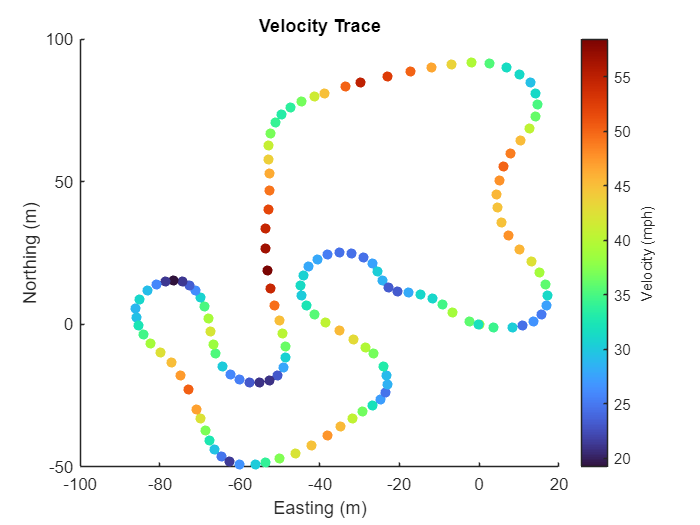

figure()
% MapColor = 255*Log(1).MVWP./max(Log(1).MVWP);
MapColor = Log(2).MVWP*2.236;
scatter(Track.EWP,Track.NWP,[],MapColor,'filled');
xlabel("Easting (m)")
ylabel("Northing (m)")
title("Velocity Trace")
colormap turbo
cbar = colorbar;
cbar.Label.String = 'Velocity (mph)';


% figure()
% plot(Track.SWP,Log(1).GY,Track.SWP,Log(2).GY)
% xlabel("Distance (m)")
% ylabel("Lateral Acceleration (G's)")
% figure()
% plot(Track.SWP,Log(1).GX,Track.SWP,Log(2).GX)
% xlabel("Distance (m)")
% ylabel("Longitudinal Acceleration (G's)")
